Практика 5. OFDM-модуляция.

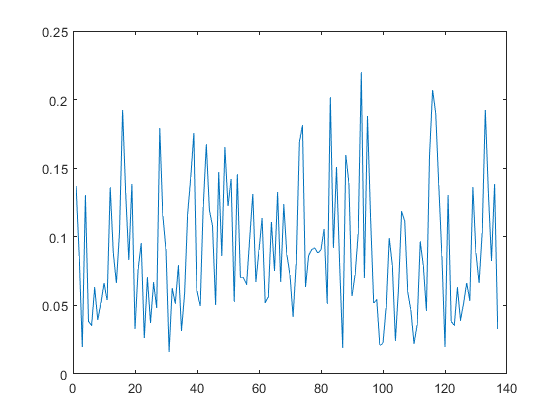

clear all;
% Кодирование сообщения
[bitArray, alphabet, codedMessage] = znakCoding(10);

% Помехоустойчивое кодирование
[convBitArray] = convCoder(bitArray);

% Перемежение
[interleavingBits, interleavingPattern] = interleavingEncoder(convBitArray);

% Модуляция QPSK
[qpskComplex] = qpskEncoder(interleavingBits);

% OFDM модуляция
[ofdmSymbCp] = ofdmModulator(qpskComplex);